# EX. 2. 

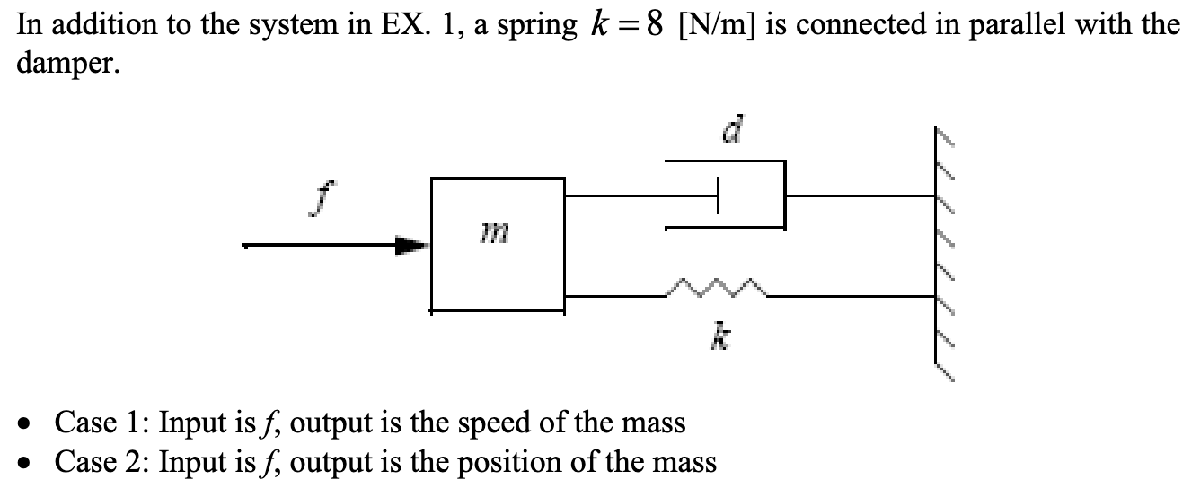

### Basic parameters

The basic parameters of the system are given in the problem description

m = 0.1; % kg
d = 0.5; % Ns/m
k = 8; % N/m

### State space and transfer function models

The state space models and transfer functions were derived on paper according to the following: 

Case 1: 

State space model:


$$A = \left( \matrix{0 & 1 \cr -k/m & -\frac{d}{m}} \right), \quad
B = \left( \matrix{0 \cr \frac{1}{m}} \right), \quad
C = \left( \matrix{0 & 1} \right), \quad
D = 0
$$


Transfer function model: 


$$G_1(s) = \frac{s}{ms^2 +ds + k}
$$


% Derived state space model for case 1:

A = [0, 1; -k/m, -d/m];

B = [0; 1/m];

C1 = [0, 1];

D = 0;


sys1 = ss(A, B, C1, D);

% Derived transfer function model for velocity output

s = tf('s');

G1 = s / (m*s^2 + d*s + k);

Case 2: 

State space model:


$$A = \left( \matrix{0 & 1 \cr -k/m & -\frac{d}{m}} \right), \quad
B = \left( \matrix{0 \cr \frac{1}{m}} \right), \quad
C = \left( \matrix{1 & 0} \right), \quad
D = 0
$$


Transfer function model: 


$$G_1(s) = \frac{1}{ms^2 +ds + k}
$$


% Derived state space model for case 2:

A = [0, 1; -k/m, -d/m];

B = [0; 1/m];

C2 = [1, 0];

D = 0;

sys2 = ss(A, B, C2, D);

% Derived transfer function model for position output
G2 = 1 / (m*s^2 + d*s + k);

## With output being the speed of the mass (case 1) 

### Bode diagram

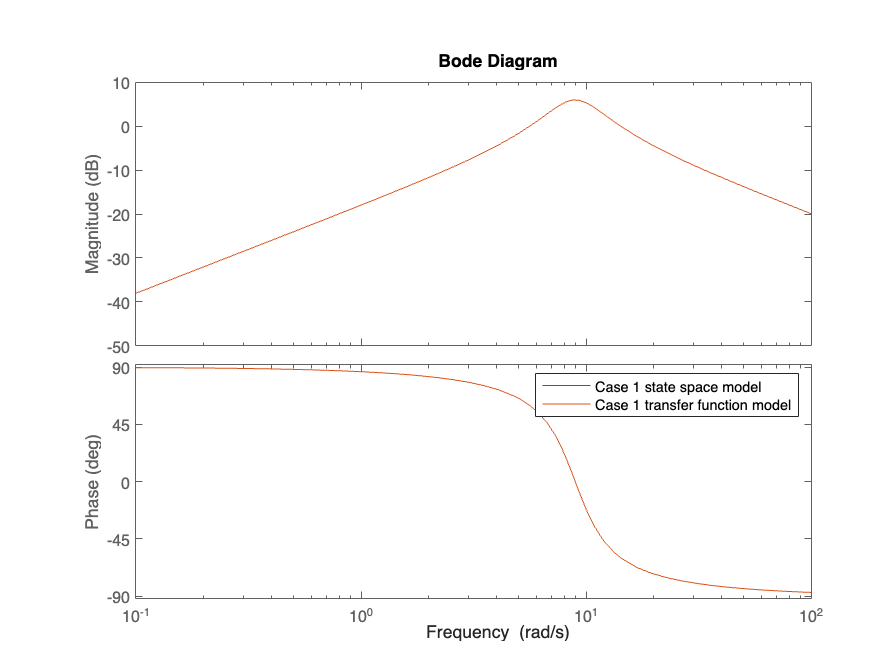

bode(sys1, G1)
legend("Case 1 state space model", "Case 1 transfer function model")


[mag, phase, w] = bode(G1);
mag = squeeze(mag);
w = squeeze(w);  
[maxGain, index] = max(mag);  
peakFrequency = w(index);       

% Display the results
fprintf('Peak Gain: %.2f\n', maxGain);

Peak Gain: 1.99


fprintf('Peak Frequency: %.2f rad/s\n', peakFrequency);

Peak Frequency: 8.70 rad/s


### Step response

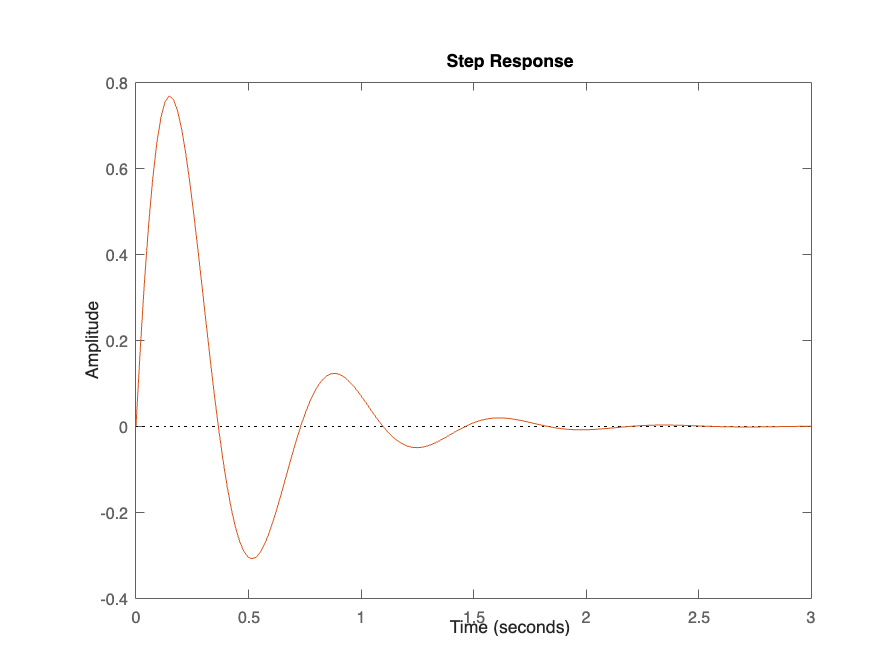


sp =

	resppack.timeplot



sp = stepplot(sys1, G1)

### Pole-zero plot

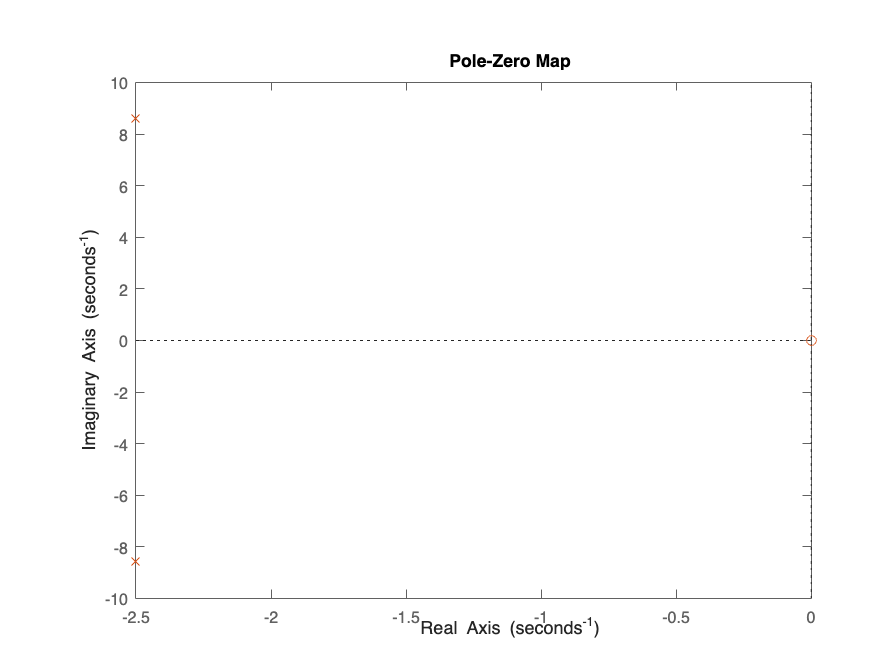


pzp =

	resppack.mpzplot



pzp = pzplot(sys1, G1)

### What are the natural resonance frequency, damped resonance frequency, and DC-gain?

The natural frequency of the system can be approximated by looking at the bode plot and finding the maxiumum. This shows that the peak, or resonance frequency is at 8,70 rad/s. For a more accurate calculation, the magnitude of the conjugate poles in the pole-zero map can be used. Calculating this magnitude, we get that the natural resonance frequency is $\sqrt{(-2,5)^2 + (8.5878)^2} = 8,944\ rad / s$. Furthermore, this natural resonance frequency can also be calculated as the undamped resonance frequency $\omega_n = \sqrt{\frac{k}{m}} = 8,944\ rad/s
$

poles = pole(sys1)

poles =   -2.5000 + 8.5878i
  -2.5000 - 8.5878i


To calculate the damped resonance frequency we can use the knowledge of the natural resonance frequency and the damping. Using equations $\zeta = \frac{d}{2 \sqrt{mk}}
$ and $\omega_d = \omega_n \sqrt{1 - \zeta^2}
$ we can calculate that the damped resonance frequency is $\omega_d = 8,588\ rad/s$. This value can also be approximated by studying the time between oscillations in the step plot, however for this system the damping means that this period of oscillation changes rapidly, and therefore this method does not provide a reliable result. 

The DC-gain of the system can be calculated by setting s = 0 in the transfer function. This gives the result $G_1(s) = \frac{0}{0 +0 + k} = \frac{0}{k} = 0
$ showing that the DC-gain is zero. This can also be observed from the step response, which shows that the response goes to 0 with a step input. Furthermore, the bode plot also shows a negative gain of almost -40dB at frequencies close to zero, also indicating this DC-gain is logical. 

The reason the resonance frequency that can be read from the pole zero map is not exactly the same as the peak frequency at peak gain in the bode plot is because the frequency derived from the pole zero map does not include complex system dynamics such as the damping of the system and the potential for phase shift when the frequency changes. This leads to the peak magnitude often being at a lower frequency than the natural resonance frequency. 

## With output being the position of the mass (case 2) 

### Step response

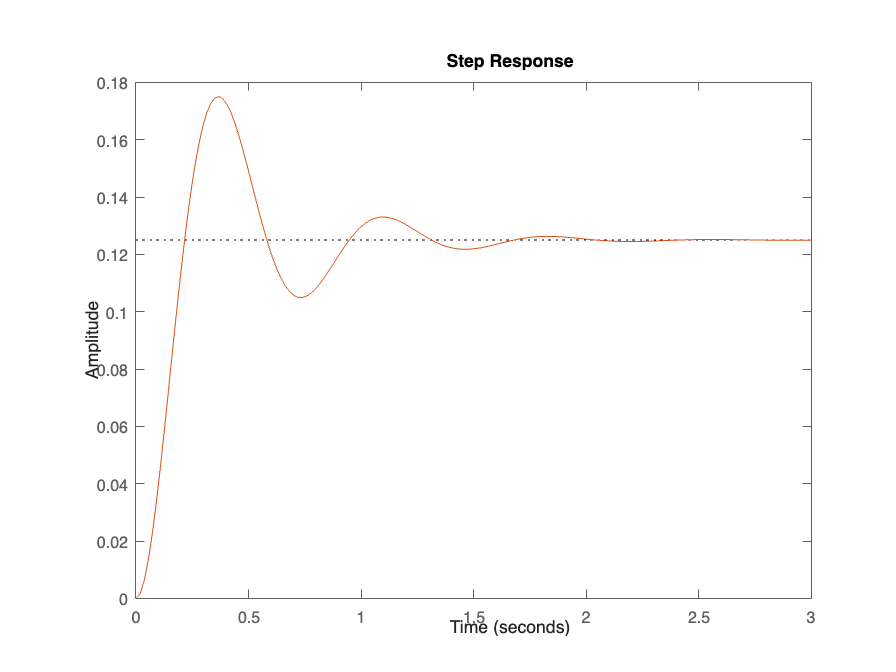


sp =

	resppack.timeplot



sp = stepplot(sys2, G2)

In this system, we can note from the previos calculations that the systems natural resonance frequency depens on the system stiffness defined as $\omega_n = \sqrt{\frac{k}{m}}$. Similarly, the damped resonance frequency is influened by the system damping ratio, defined as $\zeta = \frac{d}{2 \sqrt{mk}}
$. Both of these values are the same as in the system in case 1, the only difference is the nominator being a 1 instead of an s. This changes the DC-gain of the system, but the natural and damped resonance frequencies remain as in the previous system at  $\omega_n = 8,944\ rad/s$ and $\omega_d = 8,588\ rad/s$. The DC-gain of the system can be calculated by setting s = 0 in the transfer function. This gives the result $G_2(s) = \frac{1}{0 +0 + k} = \frac{1}{k} = 1/8 = 0,125
$ which can also be observed in the step plot. 

## Simulink

### Comparing results of both models for case 1:

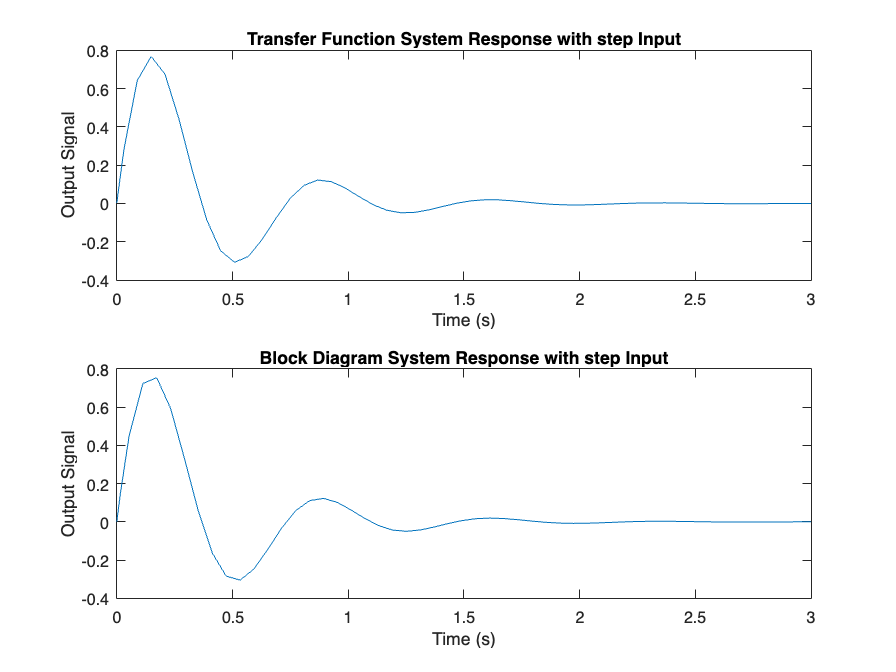

model_name = 'excercise1_2tf1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('velocity').Values.Data; 


model_name = 'excercise1_2bd'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('velocity').Values.Data; 

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');

In this graph it is possible to see that the step response of both systems is identical. Furthermore, the step response of both systems is identical to the one derived througn use of the matlab "stepplot" function. 

### Applied force as sine wave with frequency below the systems natural frequency in case 1

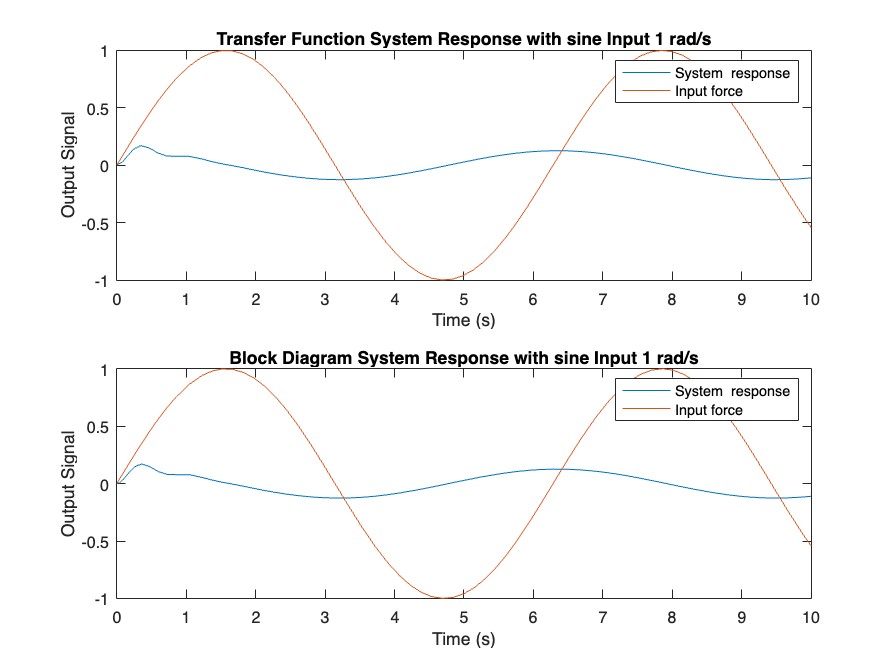

model_name = 'excercise1_2tf1';
load_system(model_name);

set_param(model_name, 'StopTime', '10');

% Choose input type: 'step' or 'sine'
input_type = 'sine';

switch input_type
    case 'step'
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(1);
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end


simOut = sim(model_name);


sim_time14 = simOut.tout;
output_signal14 = simOut.logsout.getElement('velocity').Values.Data;
input_force14 = simOut.logsout.getElement('force').Values.Data;

model_name = 'excercise1_2bd'; 
load_system(model_name);

set_param(model_name, 'StopTime', '10'); % 

input_type = 'sine';

switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

simOut = sim(model_name);

% Retrieve and plot the output
sim_time24 = simOut.tout;
output_signal24 = simOut.logsout.getElement('velocity').Values.Data;
input_force24 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time14, output_signal14);
title(['Transfer Function System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time14, input_force14);
legend("System  response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time24, output_signal24);
title(['Block Diagram System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time24, input_force24);
legend("System  response", "Input force")
hold off

### Applied force as sine wave with frequency at the systems natural frequency in case 1

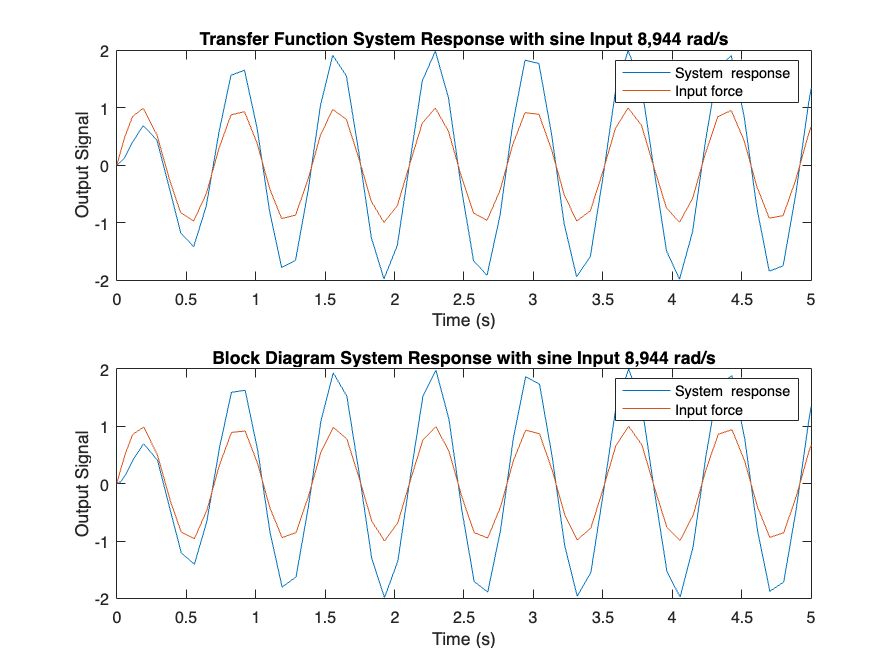

model_name = 'excercise1_2tf1';
load_system(model_name);

set_param(model_name, 'StopTime', '5');

% Choose input type: 'step' or 'sine'
input_type = 'sine';

switch input_type
    case 'step'
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(8.944);
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end


simOut = sim(model_name);


sim_time14 = simOut.tout;
output_signal14 = simOut.logsout.getElement('velocity').Values.Data;
input_force14 = simOut.logsout.getElement('force').Values.Data;

model_name = 'excercise1_2bd'; 
load_system(model_name);

set_param(model_name, 'StopTime', '5'); % 

input_type = 'sine';

switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(8.944); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

simOut = sim(model_name);

% Retrieve and plot the output
sim_time24 = simOut.tout;
output_signal24 = simOut.logsout.getElement('velocity').Values.Data;
input_force24 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time14, output_signal14);
title(['Transfer Function System Response with ' input_type ' Input 8,944 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time14, input_force14);
legend("System  response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time24, output_signal24);
title(['Block Diagram System Response with ' input_type ' Input 8,944 rad/s']);
xlabel('Time (s)')
ylabel('Output Signal');
hold on
plot(sim_time24, input_force24);
legend("System  response", "Input force")
hold off

### Applied force as sine wave with frequency at the systems natural frequency in case 1

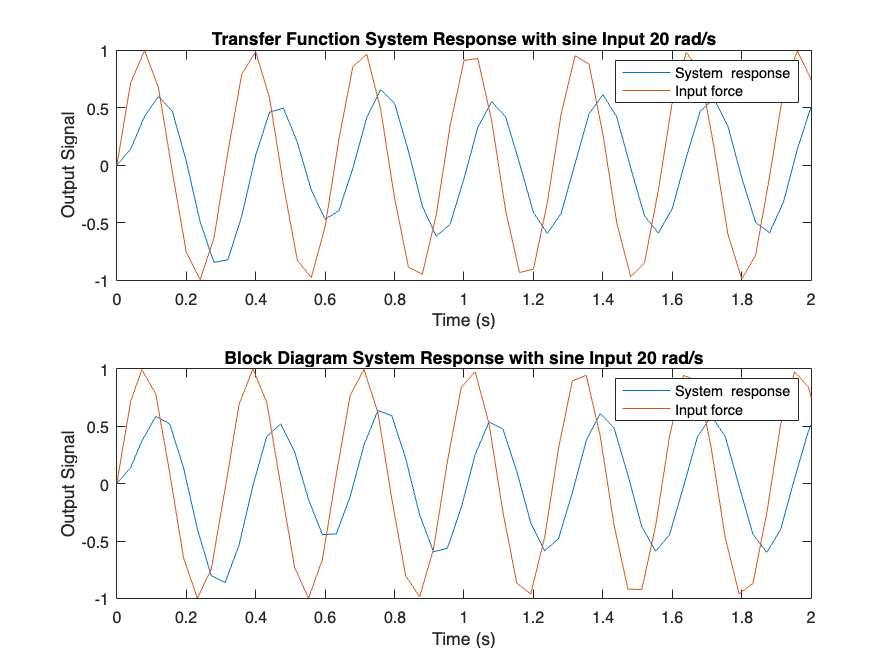

model_name = 'excercise1_2tf1';
load_system(model_name);

set_param(model_name, 'StopTime', '2');

% Choose input type: 'step' or 'sine'
input_type = 'sine';

switch input_type
    case 'step'
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(20);
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end


simOut = sim(model_name);


sim_time14 = simOut.tout;
output_signal14 = simOut.logsout.getElement('velocity').Values.Data;
input_force14 = simOut.logsout.getElement('force').Values.Data;

model_name = 'excercise1_2bd'; 
load_system(model_name);

set_param(model_name, 'StopTime', '2'); % 

input_type = 'sine';

switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

simOut = sim(model_name);

% Retrieve and plot the output
sim_time24 = simOut.tout;
output_signal24 = simOut.logsout.getElement('velocity').Values.Data;
input_force24 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time14, output_signal14);
title(['Transfer Function System Response with ' input_type ' Input 20 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time14, input_force14);
legend("System  response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time24, output_signal24);
title(['Block Diagram System Response with ' input_type ' Input 20 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time24, input_force24);
legend("System  response", "Input force")
hold off

As can be seen in these graphs, at the systems natural resonance frequency the phase shift is zero, and the system output is in phase with the force input. This can also be seen in the frequency plot where the phase is 0 degrees at the natural resonance frequency. Below the natural resonance frequency the phase shift is approximately 90 degrees, and at above the natural resonance frequency the phase shift is approximately -90 degrees. 

### Simscape

#### Simscape and simulink models with step input

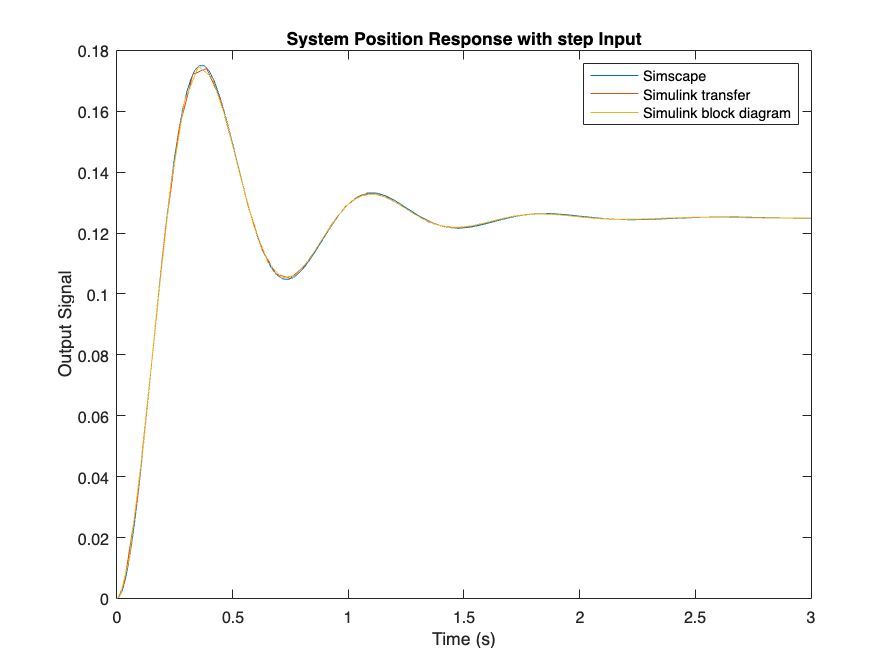

model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval1'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval1'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time17 = simOut.tout;
output_signal17 = simOut.logsout.getElement('Position Sim Ex.2').Values.Data; 


model_name = 'excercise1_2tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('position').Values.Data; 


model_name = 'excercise1_2bd'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('position').Values.Data; 


figure;
plot(sim_time17, output_signal17);
title(['System Position Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time12, output_signal12);
plot(sim_time22, output_signal22);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

As can be seen from the graph, all the systems generate the same response for a step input. 

#### Simscape and simulink models with sinusoidal inputs

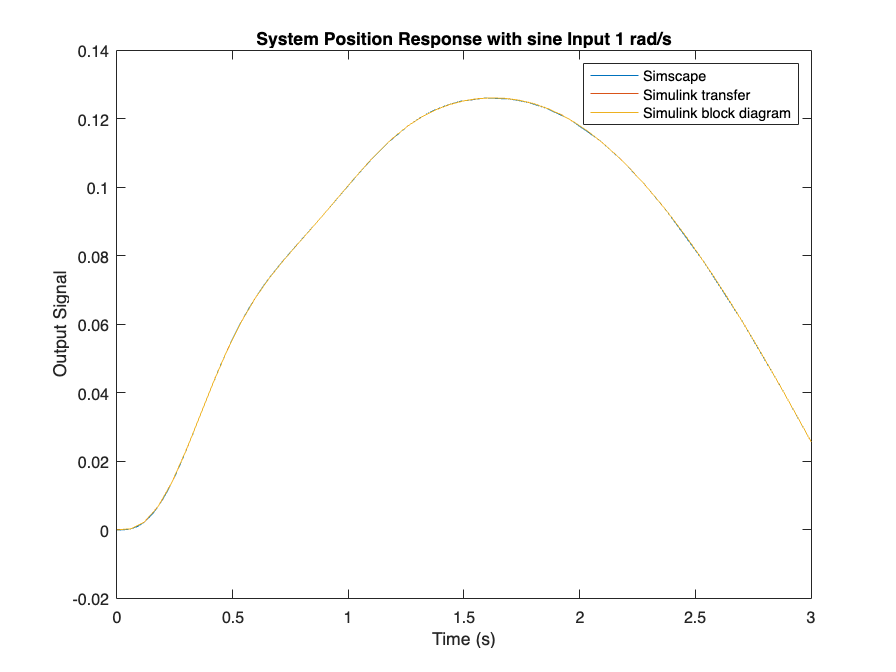

model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval1'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval1'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave1'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time17 = simOut.tout;
output_signal17 = simOut.logsout.getElement('Position Sim Ex.2').Values.Data; 


model_name = 'excercise1_2tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('position').Values.Data; 


model_name = 'excercise1_2bd'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('position').Values.Data; 


figure;
plot(sim_time17, output_signal17);
title(['System Position Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time12, output_signal12);
plot(sim_time22, output_signal22);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

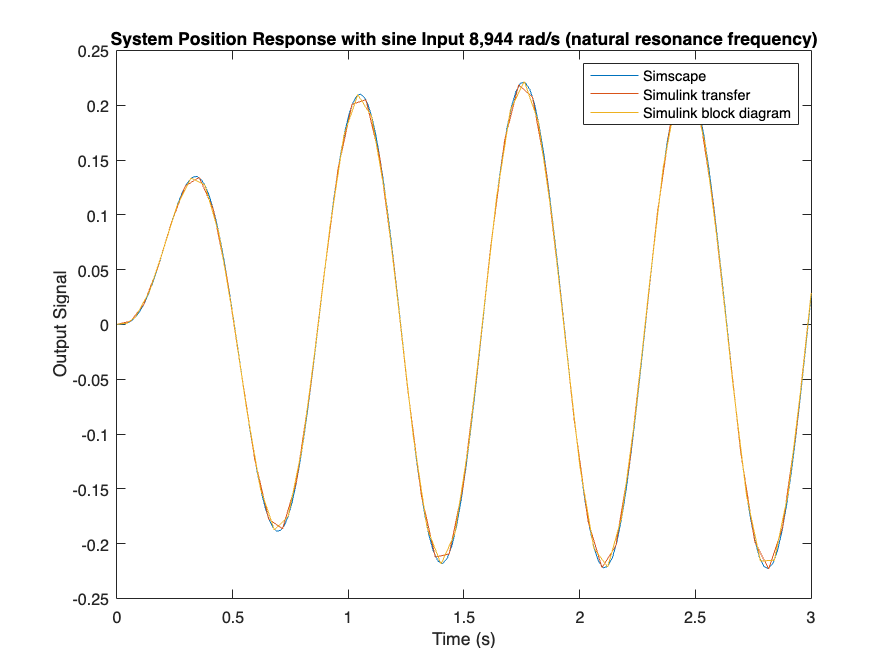

model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval1'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval1'], 'Value', '0');
        
        
        frequency = num2str(8.944); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave1'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time17 = simOut.tout;
output_signal17 = simOut.logsout.getElement('Position Sim Ex.2').Values.Data; 


model_name = 'excercise1_2tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(8.944); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('position').Values.Data; 


model_name = 'excercise1_2bd'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(8.944); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('position').Values.Data; 


figure;
plot(sim_time17, output_signal17);
title(['System Position Response with ' input_type ' Input 8,944 rad/s (natural resonance frequency)']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time12, output_signal12);
plot(sim_time22, output_signal22);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

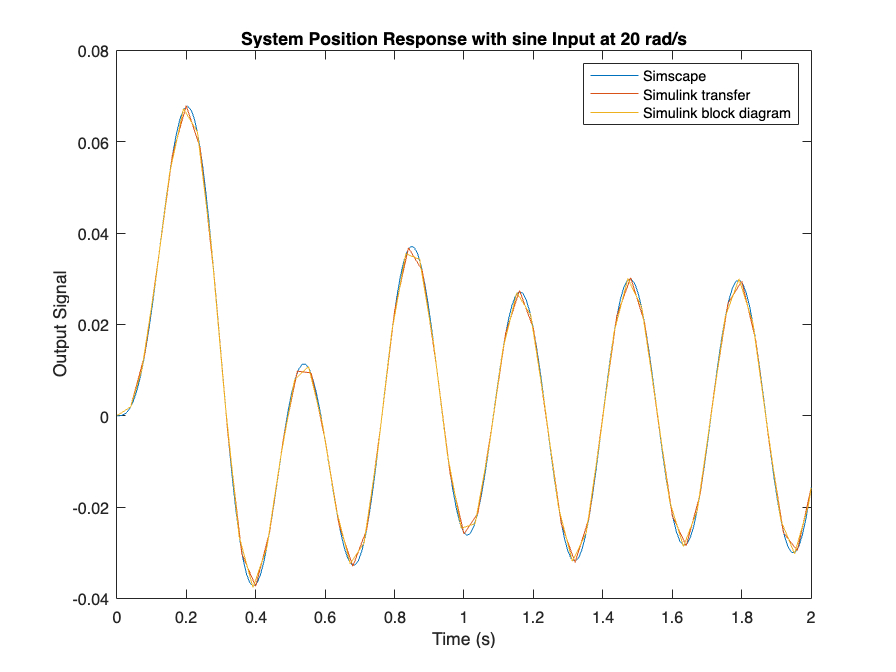

model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '2'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval1'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval1'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave1'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time17 = simOut.tout;
output_signal17 = simOut.logsout.getElement('Position Sim Ex.2').Values.Data; 


model_name = 'excercise1_2tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '2'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('position').Values.Data; 


model_name = 'excercise1_2bd'; 
load_system(model_name);


set_param(model_name, 'StopTime', '2'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('position').Values.Data; 


figure;
plot(sim_time17, output_signal17);
title(['System Position Response with ' input_type ' Input at 20 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time12, output_signal12);
plot(sim_time22, output_signal22);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

From these graphs, it is possible to see that the simscape model behaves the same as the two simulink models describing the system using a transfer function and a block diagram model. The simscape model does however have better resolution at times. 